# A Poisson problem with nonhomogeneous vertex conditions

Set up a quantum graph in the form of a dumbbell plus one extra edge

Solve the vertex-value problem 


$$\triangle u = f \\
\sum u'(\mathtt{v_1})+ u(\mathtt{v_1}) = 1 \\
\sum u'(\mathtt{v_2})+ u(\mathtt{v_2}) = 2 \\$$


where 

- The functions on the right-hand-sides are $f = \left\{\cos{x}, x, \sin{2x} \right\}$on the four edges.

- the edges have lengths $\left\{
2\pi, 4, 2\pi
\right\}$.

- The exact solutions on the edges are $\left\{
\frac{19}{2}-\cos{x}, 
\frac16 ( 51 -45 x + x^3),
 \frac{1}{12}(-130 - 3 \sin{2x}), 
\frac{1}{6} (-65 + 80 x + 3 x^2 )
\right\}$.

Exact solution computed in accompanying Mathematica notebook of the same name.

## Quantum graph definition

s=[1 1 2];
t=[1 2 2];
L=[2*pi 4 2*pi];
robinCoeff=[1 1];

## The exact solution

u1=@(x)(17/6 - cos(x));
u2=@(x)(11 - 5*x + x.^3)/6;
u3=@(x)(110 - 3*sin(2*x))/12;

## The right hand sides

Edges and nodes

f1=@(x)cos(x);
f2=@(x)x;
f3=@(x)sin(2*x);
nodeData = [1; 2];

## Solve the system twice,

doubling the number of discretization points between the two runs.

nx = [16 32];
errors=zeros(1,2);
for k=2:2

Define the quantum graph (all that changes between the two iterates is the number of discretization points per unit length).

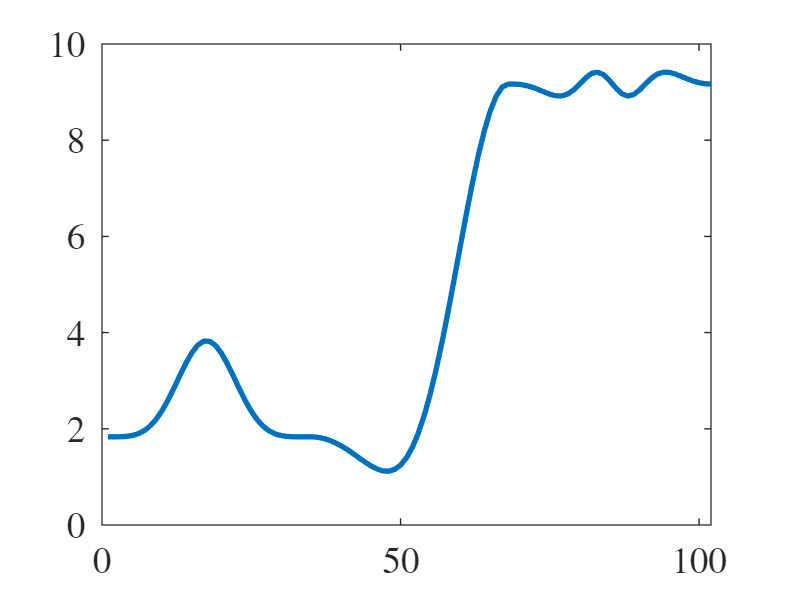

    Phi=quantumGraph(s,t,L,'Discretization','Chebyshev','RobinCoeff',robinCoeff,'nxVec',nx(k),'nodeData',nodeData);

Set up the exact solution on the edges

    exactSolution = Phi.applyFunctionsToAllEdges({u1,u2,u3});

Set up the nonhomogeneous data on the edges

    edgeData = Phi.applyFunctionsToAllEdges({f1,f2,f3});

The maximum error went down by a factor of 0.0000.


Solve and compute errors

    numericalSolution = Phi.solvePoisson('edgeData',edgeData);
    errors(k)= max(abs(exactSolution-numericalSolution));
end

Plot the solution

plot(numericalSolution)

Plot the exact solution

plot(exactSolution)

Display the reduction in error. Since the discretization is second order, this should be about a faction of four.

fprintf("The maximum error went down by a factor of %0.4f.\n", errors(1)/errors(2) )
